# Assignment 1

*David Benatia*

*Time-Series Econometrics*

*MATH60837, M.Sc.*

## ***Presented by: ***

Jérémie Couillard (11319857) 

Prateek Sinha (11306859)

Yue Zhang (11289908)

## *Instructions:*

- *To do the assignment, form a team including maximum three members.*

- *Use whatever software you prefer. *

- *Provide a detailed pdf document exported from a Python or R notebook, or MATLAB Livescript (e.g. this document). The code must be clean and easy to understand, the figures must have titles, axes must have labels, plots must have legends. Explanations, justifications, and interpretations are **required**.*

- *The assignment must be completed by **March 2, 2023**. Submit electronically in ZoneCours (remise de Travaux).*

- *One submission per team suffices.*

- *No delay will be tolerated.*

- *Any form of plagiarism is unacceptable.*

- *Download the file accessible at *[https://www.dropbox.com/s/vfq5cfz9dibzobv/data_W2023.csv?dl=0.](https://www.dropbox.com/s/vfq5cfz9dibzobv/data_W2023.csv?dl=0.) * It contains data on the bilateral foreign exchange rate between the US dollar and the Canadian dollar.*

## Questions

### Part 1. Preliminary analysis (20 points)

Let us define $y_t= \log(100 \times USDCAD_t)$the series of interest throughout this assignement.

**1.**

clc
close all
clear all

**a) Load the data and keep only the observations up to December 2019. Plot the raw series **$y_t$** with labels on each axis and a title 'log(100 USDCAD=x)'. The time dimension must appear on the x-axis.**

data = readtable("data_W2023.csv");

nrow = height(data);
% look at the last row which is Dec 2019
data(nrow,:)

ans = 1×2 table
       date       shareprice
    __________    __________

    2019-12-01      1.019   


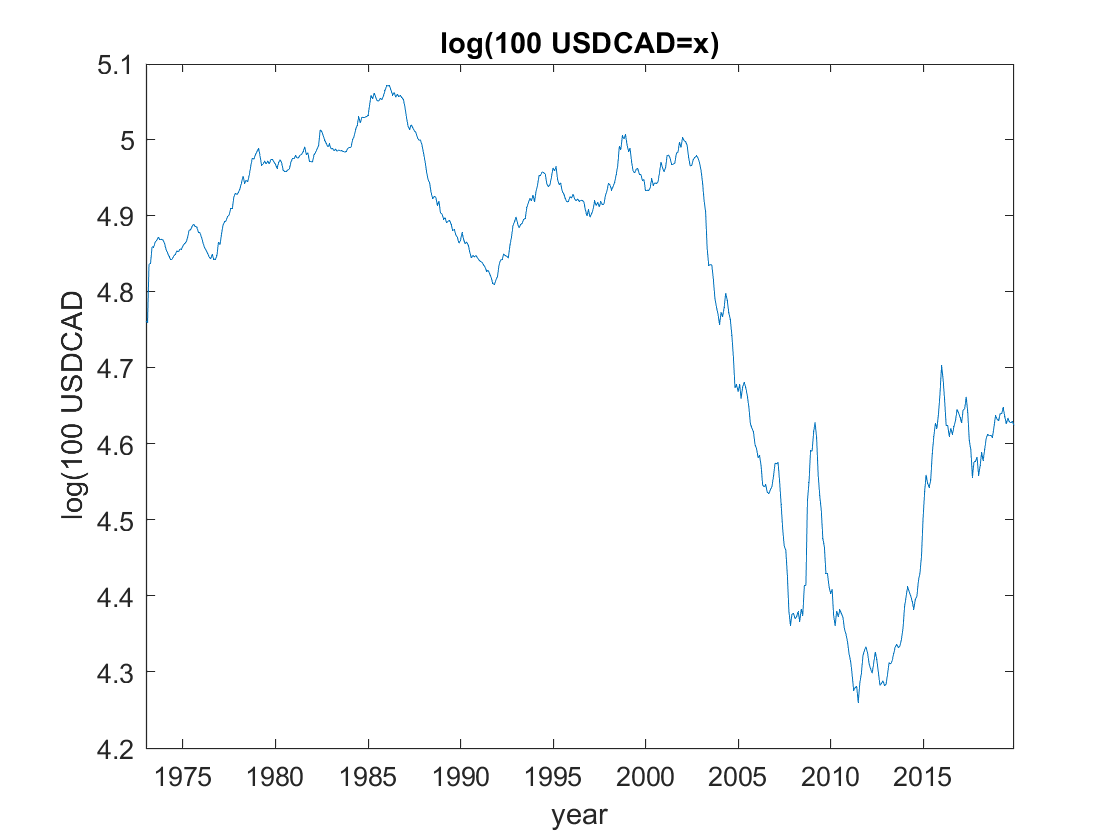

% plot log price
sp = data.shareprice;
lsp = log(100*sp);

figure
plot(data.date,lsp)
title('log(100 USDCAD=x)')
xlabel('year')
ylabel('log(100 USDCAD')

Interpretation:

The plot shows that the time series log USDCAD may have a non-linear trend and therefore is not be staionary. 

**1.b) Assume there is a deterministic (2nd order polynomial) time trend: **$\tau_t = \alpha + \beta t + \gamma t^2$**. Apply the transformation required to stationarize the log series (the log of the exchange rate) and plot the resulting series.**

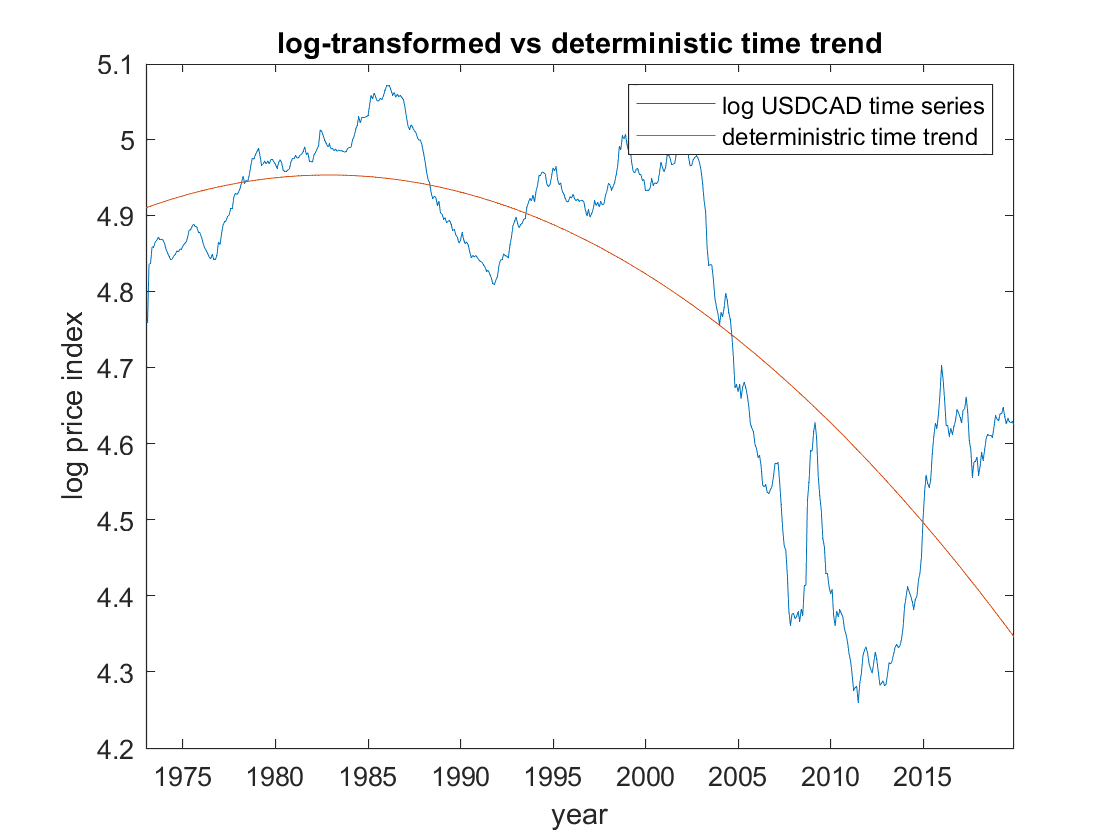

% linear regression 

T = length(lsp);
trend = 1 : T; %generate a linear time trend
X = [ones([T,1]), trend(:), trend(:).^2]; %covariates
Y = lsp; %dependent var
B = X\Y; %MATLAB shortcut to solve A*X = B: the same as OLS solution (X'X)^-1 X'Y

plot(data.date,lsp)
title('log-transformed vs deterministic time trend')
xlabel('year')
ylabel('log price index')

hold on
plot(data.date,B(1) + B(2)*trend +B(3)*trend.^2)
legend('log USDCAD time series','deterministric time trend')
hold off

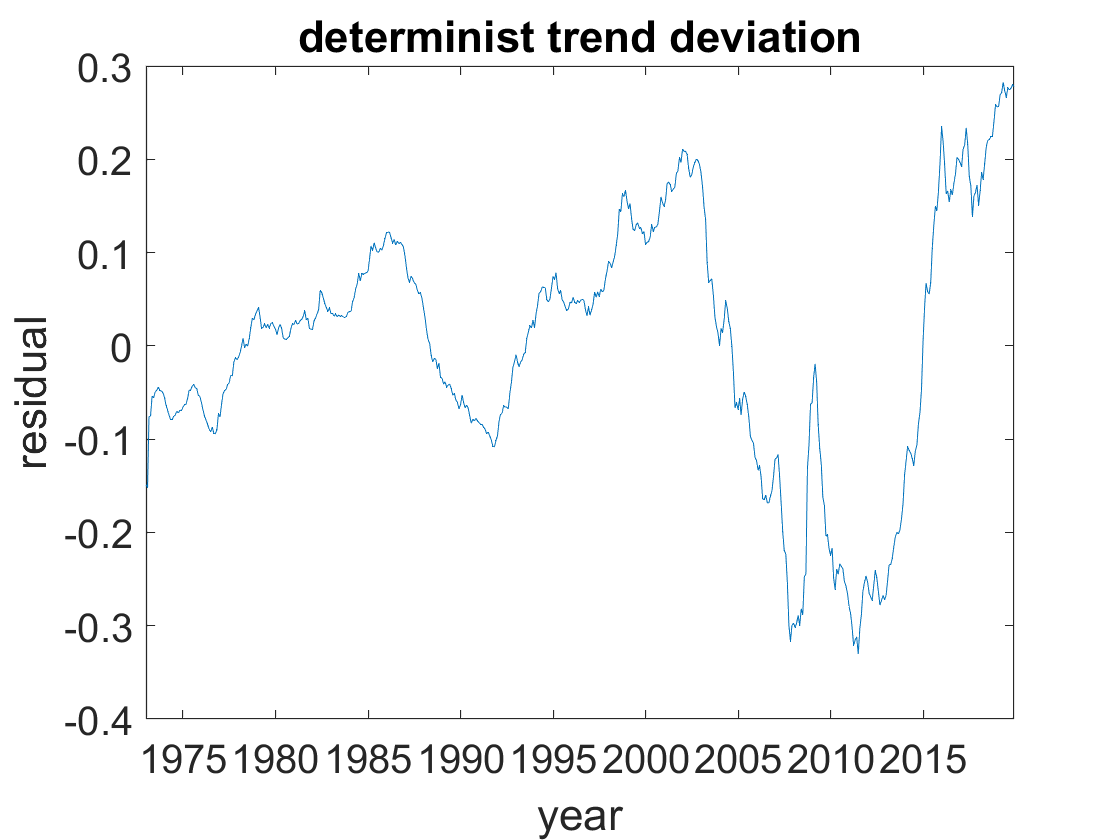

%detrend series
c_sp = Y - X*B; 

plot(data.date,c_sp)
title('determinist trend deviation')
xlabel('year')
ylabel('residual')    
set(gca,'FontSize',15)

Interpretation:   

By assuming the trend is deterministic, we regress the log exchange rate time series against the 2nd order polynomial time trend.  If the resulting series is a stationary, we imply that the time trend is deterministic. However, the residuals from the detrending of the series using a deterministic approach are not stationary when looking at the chart. We should try a different transformation such as the first difference of the series to stationarize the log series.

**1.c) Assume there is a stochastic time trend, i.e. a random walk. Apply the transformation required to stationarize the log series (the log of the exchange rate) and plot the resulting series.**

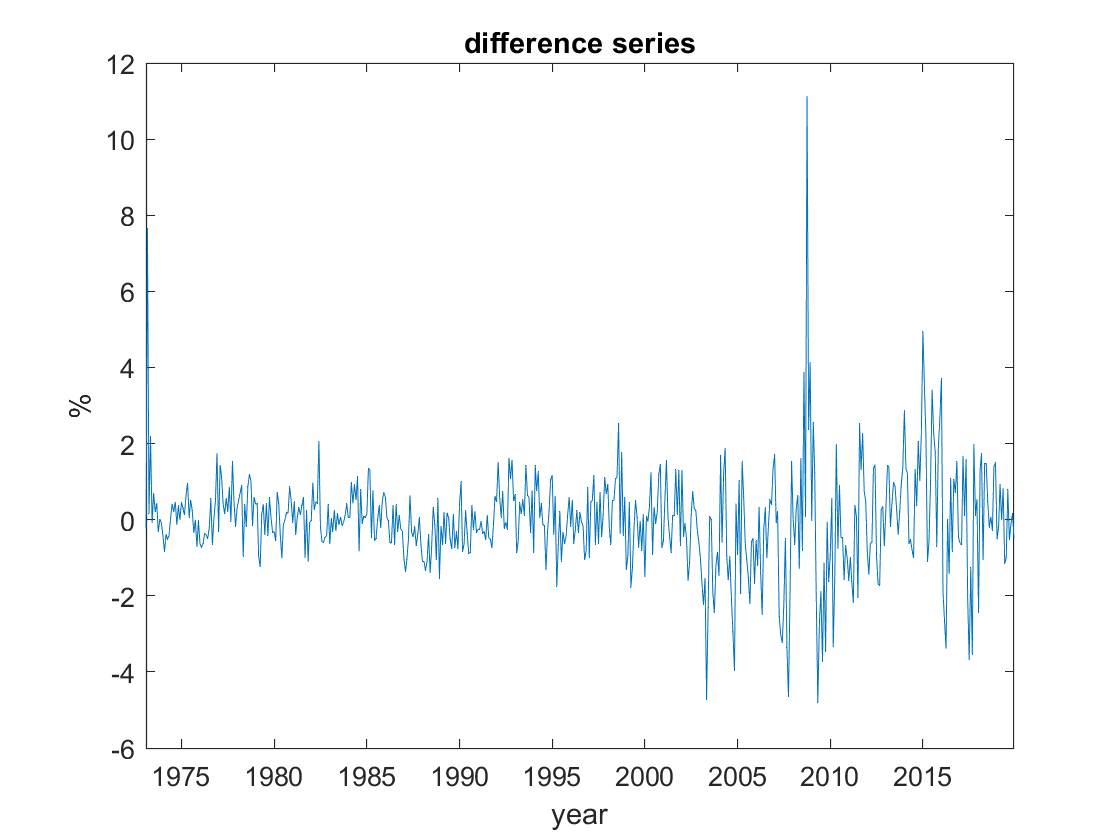

d_sp = diff(lsp)*100; %diff gives first-difference, hence growth rate, x100 gives percentages.

figure
plot(data.date(2:end),d_sp)
title('difference series')
xlabel('year')
ylabel('%')

Interpretation:

By assuming the trend is stochastic, we use first difference to the log series and the resulting series looks much more stationary. We will confirm its stationary properties by analyzing at its autocorrelation function. 

**1.d) Analyze the sample autocorrelation functions to evaluate if the series are stationary. Which series would you choose two estimate a time-series model?**

[acf1] = autocorr(d_sp,18)

acf1 =     1.0000
    0.3358
    0.3440
    0.0880
    0.1763
    0.0606
    0.0418
   -0.0496
   -0.0261
   -0.0210


[acf2] = autocorr(c_sp,18)

acf2 =     1.0000
    0.9904
    0.9776
    0.9627
    0.9470
    0.9298
    0.9123
    0.8942
    0.8764
    0.8591


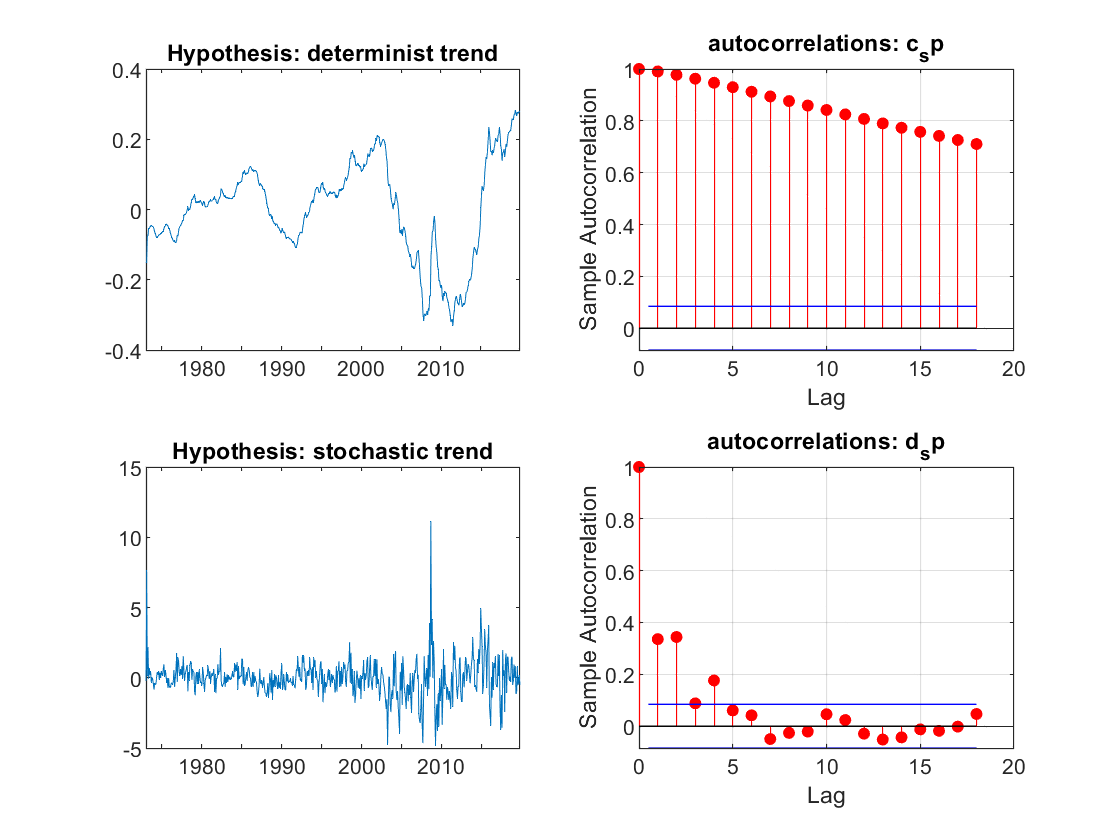


figure
subplot(2,2,1);
plot(data.date,c_sp);
title('Hypothesis: determinist trend'); 
set(gca,'FontSize',8);

subplot(2,2,2);
autocorr(c_sp,18);
title('autocorrelations: c_sp');
set(gca,'FontSize',8);

subplot(2,2,3);
plot(data.date(1:T-1),d_sp);
title('Hypothesis: stochastic trend') ;
set(gca,'FontSize',8);

subplot(2,2,4);
autocorr(d_sp,18);
title('autocorrelations: d_sp');
set(gca,'FontSize',8);

title('Hypothesis: stochastic trend') ;
set(gca,'FontSize',8);

subplot(2,2,4);
autocorr(d_sp,18);
title('autocorrelations: d_sp');
set(gca,'FontSize',8);

Interpretation:

We process the autocorrelation analysis to the regression based detrended series and the first difference series. The autocorrelation function of the residuals of the deterministic transformation do not converge rapidly to zero and shows a persistance effect. As such, we can conclude that this series is not stationary. 

On the other hand, the autocorrelation function of the first difference transformation converges rapidly to zero. As such, we can conclude that the first difference series has stationary properties and that the log USDCAD series follows a stochastic trend. 

**1.e) From now on, use exclusively the series which is stationary. Perform the Ljung-Box tests with 1 to 18 lags to verify if the series is white noise and conclude.**

% We are using the first difference series as we assumed from the ACF that
% it is the stationary series.

[h,pValue,stat] = lbqtest(d_sp, Alpha=0.05, Lags = [1:18])

h = 1×18 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


pValue = 1.0e-14 *

    0.1332         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


stat =    63.8379  130.9329  135.3303  153.0147  155.1088  156.1085  157.5143  157.9035  158.1579  159.3689  159.6946  160.1765  161.7152  162.7938  162.8840  163.0723  163.0742  164.3676


tb_lbq = table(h',pValue',stat');
tb_lbq.Properties.VariableNames = ["h","pValue","stat"]  

tb_lbq = 18×3 table
      h        pValue       stat 
    _____    __________    ______

    true     1.3323e-15    63.838
    true              0    130.93
    true              0    135.33
    true              0    153.01
    true              0    155.11
    true              0    156.11
    true              0    157.51
    true              0     157.9
    true              0    158.16
    true              0    159.37
    true              0    159.69
    true              0    160.18
    true              0    161.72
    true              0    162.79
    true              0    162.88
    true              0    163.07


Interpretation:

The Ljung-Box test has null hypothesis that the series is white noise, whose autocorelation for all 1 to 18 lags are zero. cov(yt, yt-i) = 0 where i = 1 to 18; against the alternative hypothesis that there is at least one lag (t-i) where i is not zero, and has a significant amount of autocorrelation with yt. 

The pvalue of lags from 1 to 18 are zeros telling that there is significant evidence that we can reject the null hypothesis at 5% significant level and favor the alternative hypothesis that the series is not a white noise.  

### Part 2. Model selection (30 points)

Let us consider the following 8 models:

AR(1): $y_t = \delta + \phi y_{t-1} + u_t$  

AR(2): $y_t = \delta + \phi_1 y_{t-1}  + \phi_2 y_{t-2} + u_t$  

AR(3): $y_t = \delta +  \phi_1 y_{t-1}+ \phi_2 y_{t-2}+ \phi_3 y_{t-3}+ u_t$  

AR(4): $y_t = \delta + \phi_1 y_{t-1}  + \phi_2 y_{t-2} + \phi_3 y_{t-3} + \phi_4 y_{t-4} + u_t$  

ARMA(1,1): $y_t = \delta + \phi_1 y_{t-1}  + u_t - \theta_1 u_{t-1}$  

ARMA(2,2): $y_t = \delta + \phi_1 y_{t-1}  + \phi_2 y_{t-2}  + u_t - \theta_1 u_{t-1} - \theta_2 u_{t-2}$  

ARMA(3,3): $y_t = \delta + \phi_1 y_{t-1}  + \phi_2 y_{t-2} + \phi_3 y_{t-3}  + u_t - \theta_1 u_{t-1} - \theta_3 u_{t-2} - \theta_2 u_{t-3}$  

ARMA(4,4): $y_t = \delta + \phi_1 y_{t-1}  + \phi_2 y_{t-2} + \phi_3 y_{t-3} + \phi_4 y_{t-4}  + u_t - \theta_1 u_{t-1} - \theta_2 u_{t-2} - \theta_3 u_{t-3} - \theta_4 u_{t-4}$  

**2.a) Estimate all 8 models by maximum likelihood, report the estimation results, and verify if the stationarity conditions are satisfied.**

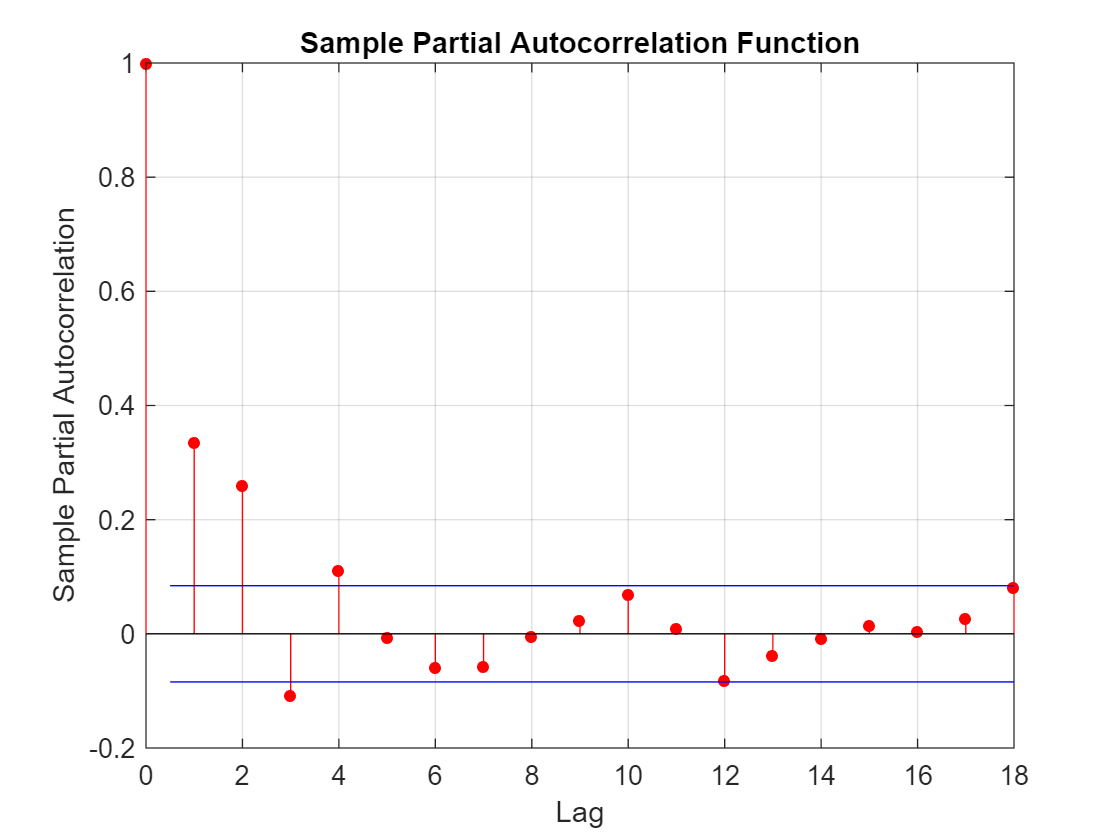

% first, we plot paraucorrelation to identify the pbar 
figure
parcorr(d_sp,18);  

%The i-order partial-autocorrelation is small when i>4. For this reason, pbar is fixed to 4.

% initialization 

m_ll = zeros(8, 3);
m_S = zeros(8,4);
m_eig = zeros(8,4);

pbar = 4;

% we use loop to estimate the 8 models, and store the estimation results 
% we test the stationarity conditions are satified by test the eigenvalue
% associated to phi matrix 

ind = 1;
for ma = 0:1

    for p = 1:4 
        q = ma * p;
        % estimate model 
        Mdl = arima(p,0,q);
        [results(ind),Cov,ll,info] = estimate(Mdl, d_sp);

        % keep log likehood value for each model 
        m_ll(ind,1) = p;
        m_ll(ind,2)  = q;
        m_ll(ind,3) = ll;


        % verify stationary 
        % build phi matrix 
        n = length(results(ind).AR);
        m_phi = zeros(n, n);
        phi = zeros(n,1);

        for i = 1:n
            phi(i) = results(ind).AR{i};
        end 

        if n == 1
            m_phi = [phi];
        else 
            newcol = zeros(p-1,1);
            m_low = [eye(n-1) newcol];   % create diagonal matrix 
            m_phi = [phi'; m_low];
        end 

        % compute eignevalue  
        [V,D] = eig(m_phi);

        % compute the S if the eigenvalue is complex number 
        for i = 1:p
            m_eig(ind, i) = D(i, i);
            m_S(ind,i) = sqrt(real(D(i,i)).^2 + imag(D(i,i)).^2);
        end

        ind = ind + 1;
    end 

end 

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.016512      0.057033        -0.28953        0.77218
    AR{1}         0.33594      0.031017          10.831     2.4567e-27
    Variance       1.5346      0.035089          43.733              0

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.011331       0.05449        -0.2079


% convert matrix to table with label 
colNames = {'p','q','LL'};

colNames2 = {'eiv1', 'eiv2','eiv3','eiv4'};

RowNames = {'AR1','AR2', 'AR3', 'AR4','ARMA11','ARMA22','ARMA33','ARMA44'};

tb_ll = array2table(m_ll,'VariableNames',colNames);

tb_eig = array2table(m_eig, 'VariableNames',colNames2, 'RowNames',RowNames);

tb_S = array2table(m_S,'VariableNames',colNames2, 'RowNames',RowNames);

tb_ll

tb_ll = 8×3 table
    p    q      LL   
    _    _    _______

    1    0    -919.41
    2    0    -896.82
    3    0    -892.53
    4    0    -888.31
    1    1    -907.39
    2    2    -882.19
    3    3    -879.65
    4    4    -874.22




% eigenvalue of phi matrix 
tb_eig

tb_eig = 8×4 table
                    eiv1                 eiv2                  eiv3                 eiv4       
              _________________    _________________    __________________    _________________

    AR1        0.33594+0i                 0+0i                 0+0i                 0+0i       
    AR2        0.67313+0i          -0.43934+0i                 0+0i                 0+0i       
    AR3       -0.61643+0i           0.44181+0.13076i     0.44181-0.13076i           0+0i       
    AR4        -0.7411+0i           0.71583+0i           0.15415+0.46939i     0.15415-0.46939i 
    ARMA11     0.71678+0i                 0+0i                 0+0i                 0+0i       
    ARMA22    -0.83754+0i            0.6745+0i                 0+0i   

tb_S

tb_S = 8×4 table
               eiv1       eiv2       eiv3       eiv4  
              _______    _______    _______    _______

    AR1       0.33594          0          0          0
    AR2       0.67313    0.43934          0          0
    AR3       0.61643    0.46076    0.46076          0
    AR4        0.7411    0.71583    0.49406    0.49406
    ARMA11    0.71678          0          0          0
    ARMA22    0.83754     0.6745          0          0
    ARMA33    0.71908    0.74504    0.74504          0
    ARMA44    0.77841    0.77841     0.7138     0.7138


Interpretation:

We built the phi matrix from each model and computed the eigenvalues of the phi matrix associated to all the lags to verify if the model is stationary or not. The condition for stationarity is that the absolute real eigenvalue for all the lags are less than 1 or the sqrt(a^2 + b^2) are less than 1 for complex eigenvalue. 

The table above shows all eigenvalue for the 8 models meet the condition therefore we can tell that the eight models are stationary. 

**2.b) Perform likelihood ratio tests to justify the selection of ****two models.**** First select the best among AR(1), AR(2), AR(3) and AR(4). Second select the best among ARMA(1,1), ARMA(2,2), ARMA(3,3), ARMA(4,4). Use the BIC to justify the selection of the best of those two models.**

1) Likelihood ratio test for the AR models  

% H0: AR1; 
% Ha: AR2
lr = 2.0*(m_ll(2,3)-m_ll(1,3))

lr = 45.1804

pvalue = 1 - chi2cdf(lr,1)  %setting the degree of freedom to 1 because we have 1 restriction

pvalue = 1.7969e-11

% The p-value for the likelihood ratio test between the AR(1) vs AR(2) is
% lower than 0.05. Therefore, we reject H0: AR(1) and accept H1: AR(2) at
% 5% significant level 

% now, we test between AR2 and AR3
% H0: AR2
% Ha: AR3
lr = 2.0*(m_ll(3,3)-m_ll(2,3))

lr = 8.5772

pvalue = 1 - chi2cdf(lr,1)  %setting the degree of freedom to 1 because we have 1 restriction

pvalue = 0.0034


% The p-value for the likelihood ratio test between the AR(2) vs AR(3) is
% lower than 0.05. Therefore, we reject H0: AR(2) and accept H1: AR(3) at
% 5% significant level 

% Now, we test AR3 and AR4
% H0: AR3; Ha: AR4
lr = 2.0*(m_ll(4,3)-m_ll(3,3))

lr = 8.4367

pvalue = 1 - chi2cdf(lr,1)

pvalue = 0.0037

% The p-value for the likelihood ratio test between the AR(3) vs AR(4) is
% lower than 0.05. Therefore, we reject H0: AR(3) and accept H1: AR(4) at
% 5% significant level 



2) Likelihood ratio test for the ARMA models 

% H0: ARMA11; Ha: ARMA22
lr = 2.0*(m_ll(6,3)-m_ll(5,3))

lr = 50.3993


pvalue = 1 - chi2cdf(lr,2)   %setting the degree of freedom to 2 because we have 2 restrictions

pvalue = 1.1374e-11


% The p-value for the likelihood ratio test between the ARMA(1,1) vs ARMA(2,2) is
% lower than 0.05. Therefore, we reject H0: ARMA(1,1) and accept H1: ARMA(2,2)

% H0: ARMA22; Ha: ARMA33
lr = 2.0*(m_ll(7,3)-m_ll(6,3))

lr = 5.0736

pvalue = 1 - chi2cdf(lr,2)

pvalue = 0.0791

% The p-value for the likelihood ratio test between the ARMA(2,2) vs ARMA(3,3) is
% higher than 0.05. Therefore, there is no significant evidence to reject H0: ARMA(2,2) at 5% level

% now we compare ARMA(2,2) and ARMA(4,4) 
lr = 2.0*(m_ll(8,3)-m_ll(6,3))

lr = 15.9443

pvalue = 1 - chi2cdf(lr,4) %setting the degree of freedom to 4 because we have 4 restrictions

pvalue = 0.0031

% The p-value for the likelihood ratio test between the ARMA(2,2) vs ARMA(4,4) is
% lower than 0.01. Therefore, signficiant evidence to reject H0: ARMA(2,2) and accept H1:
% ARMA(4,4)

BIC test for the two selected model AR(4) and ARMA(4,4) 

% BIC 
BIC_AR4 = -2*m_ll(4,3)+log(length(d_sp)-pbar)*(4+0+1)

BIC_AR4 = 1.8083e+03

BIC_ARMA44 = -2*m_ll(8,3)+log(length(d_sp)-pbar)*(4+4+1)

BIC_ARMA44 = 1.8054e+03

Interpretation: 

We choose the best model among AR(1), AR(2), AR(3), and AR(4) using likelihood ratio test by comparing all lags. 

The test results pvalue between each lag pair tell us that AR(4) is the best model.  

Processing the same procedure to the ARMA models, we choose ARMA(4,4) as the best model. 

Then, we compute the BIC for AR(4) and ARMA(4,4) and notice that ARMA(4,4) has a slightly lower BIC. 

**2.c) Evaluate the white noise hypothesis for each of the two models, and for the AR(1). What can we conclude?**

% residual of AR1 model 
mdl = arima(1,0,0); %AR(1)
AR1 = estimate(mdl,d_sp,'display','off');
[u_sp, var] = infer(AR1, d_sp); %extract residuals
[h,pValue,stat] = lbqtest(u_sp,'lags',1:18);

table(h',pValue',stat')

ans = 18×3 table
    Var1        Var2        Var3 
    _____    __________    ______

    true       0.037695    4.3188
    true     1.0616e-10    45.932
    true     7.2703e-11    50.192
    true     1.8485e-13    65.682
    true     7.9925e-13    65.708
    true     1.6469e-12    67.046
    true     1.7124e-12    69.683
    true     5.6281e-12    69.704
    true      1.293e-11    70.362
    true     1.6736e-11    72.187
    true     4.0754e-11    72.502
    true     9.2307e-11    72.879
    true     1.6628e-10    73.698
    true     3.2825e-10    74.225
    true     7.7077e-10    74.258
    true     1.6513e-09     74.43



% residual of AR4 model 
mdl = arima(4,0,0); %AR(4)
AR4 = estimate(mdl,d_sp,'display','off');
[u_sp, var] = infer(AR4, d_sp); %extract residuals
[h,pValue,stat] = lbqtest(u_sp,'lags',1:18);

table(h',pValue',stat')

ans = 18×3 table
    Var1      Var2        Var3  
    _____    _______    ________

    false    0.86396    0.029357
    false    0.74008     0.60199
    false    0.79734      1.0161
    false    0.89388      1.1025
    false    0.88069      1.7644
    false    0.82446      2.8742
    false    0.70404       4.638
    false    0.63308      6.1263
    false    0.68303       6.558
    false    0.53748      8.9434
    false    0.49066      10.447
    false    0.51047      11.216
    false    0.48559      12.519
    false    0.50623      13.259
    false    0.57908      13.301
    false    0.62826      13.603



% residual of ARMA44 model 
mdl = arima(4,0,4); %ARMA(4,4)
ARMA44 = estimate(mdl,d_sp,'display','off');
[u_sp, var] = infer(ARMA44, d_sp); %extract residuals
[h,pValue,stat] = lbqtest(u_sp,'lags',1:18);

table(h',pValue',stat')

ans = 18×3 table
    Var1      Var2        Var3  
    _____    _______    ________

    false    0.91607    0.011107
    false    0.94908     0.10452
    false    0.83248     0.87074
    false    0.81405      1.5707
    false    0.39075      5.2104
    false    0.49479      5.3905
    false     0.4386      6.9072
    false    0.45879      7.7447
    false    0.51874      8.1536
    false    0.21816        13.1
    false    0.19426      14.749
    false    0.22973      15.218
    false    0.20369      16.905
    false     0.2419      17.273
    false    0.29641      17.384
    false    0.35035      17.559


Interpretation:

We process the LB test to AR(1), AR(4), ARMA(4,4). The null hypothesis (H0) is that the residual series is a white noise (cov(ut, ut-i) = 0 for all i = 1, 2,.. 18), and alternatie hyphothsis (H1) is that the residual series is not a white noise. The pvalue of lag 1 to 18 for AR(1) is significant at 5% therefore we reject H0 and accept H1 that the residuals of AR(1) don't follow a white noise process, suggesting that the AR(1) lag structure can't catch the dynamics of the first difference series.  

Further, the pvalue of lag 1 to 18 for AR(4) and AR(4,4) are all greater than 10%, implying that we can't reject H0 that the residuals for the two selected models are white noise, therefore, the lag structures are adequate to catch the dynamics of the time series.

### Part 3. Dynamic Response and forecasting (20 points)

**3.a) For the two selected models, evaluate the dynamic response for an horizon of 10 periods following a positive shock of size **$\sigma=1.15$** occuring at the first period of the horizon. Plot the two impulse response functions on the same figure and comment. **

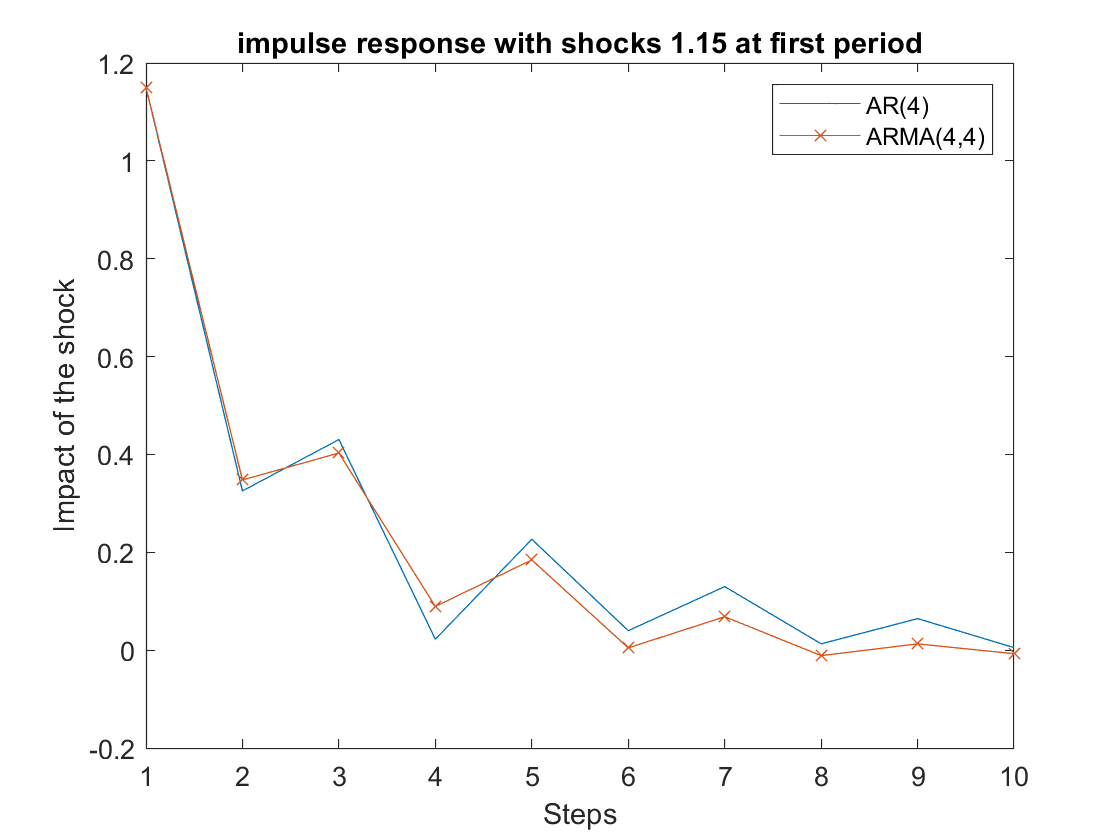

sig = 1.15;
psi_AR4 = impulse(results(4),'numobs',10)*sig;   % model AR(4)
psi_ARMA44 = impulse(results(8),'numobs',10)*sig;   % model ARMA(4,4)

%% GRAPH IMPULSE RESPONSE 
figure
plot(1:10,psi_AR4,1:10,psi_ARMA44,'-x')
legend('AR(4)','ARMA(4,4)')
xlabel('Steps')
ylabel('Impact of the shock')
title('impulse response with shocks 1.15 at first period')

results(4).AR  % AR(4) phi

ans = 1×4 cell array
    {[0.2830]}    {[0.2942]}    {[-0.1697]}    {[0.1295]}


results(8).AR   %AR(4,4) phi

ans = 1×4 cell array
    {[-0.0830]}    {[1.0015]}    {[0.0941]}    {[-0.3087]}


tb_eig(4,:)         % eigenvalue of AR(4)

ans = 1×4 table
            eiv1       eiv2            eiv3                eiv4      
           _______    _______    ________________    ________________

    AR4    -0.7411    0.71583    0.15415+0.46939i    0.15415-0.46939i


tb_eig(8,:)         % eigenvale of ARMA(4,4)

ans = 1×4 table
                    eiv1                 eiv2                 eiv3                 eiv4       
              _________________    _________________    _________________    _________________

    ARMA44    -0.74853+0.21363i    -0.74853-0.21363i    0.70704+0.098007i    0.70704-0.098007i


results(8).MA       % theta

ans = 1×4 cell array
    {[0.3855]}    {[-0.6260]}    {[-0.2903]}    {[0.0961]}


Interpretation:

We see that for both the AR(4) and the ARMA(4,4) models, the response starts from sigma (1.15), corresponding to the shock at period 1, and converges downward to zero quickly. The effect of the shock is transitory, which makes sense since we confirmed in the previous numbers that both models are stationary: the dynamic response tends to zero when i is relatively large. 

Additionally, both models have negative eigenvalue leading the dynamic response to be oscillatory. 

The absolute value of lambda is relatively small therefore the response converges to zero quickly. 

Although complex lambdas cause dynamic responses to be cyclic for intervals larger than one period, this effect is not strong in the AR(4). This weak effect could be explained by the other two larger (real) lambda values. 

**3.b) A ****negative**** shock of size **$\sigma=1.15$** occurs during 3 consecutive periods of the horizon (t, t+1, t+2). Plot the two impulse response functions for the two selected models, showing the dynamic response for an horizon of 20 periods following thse shocks, and explain what happens.**

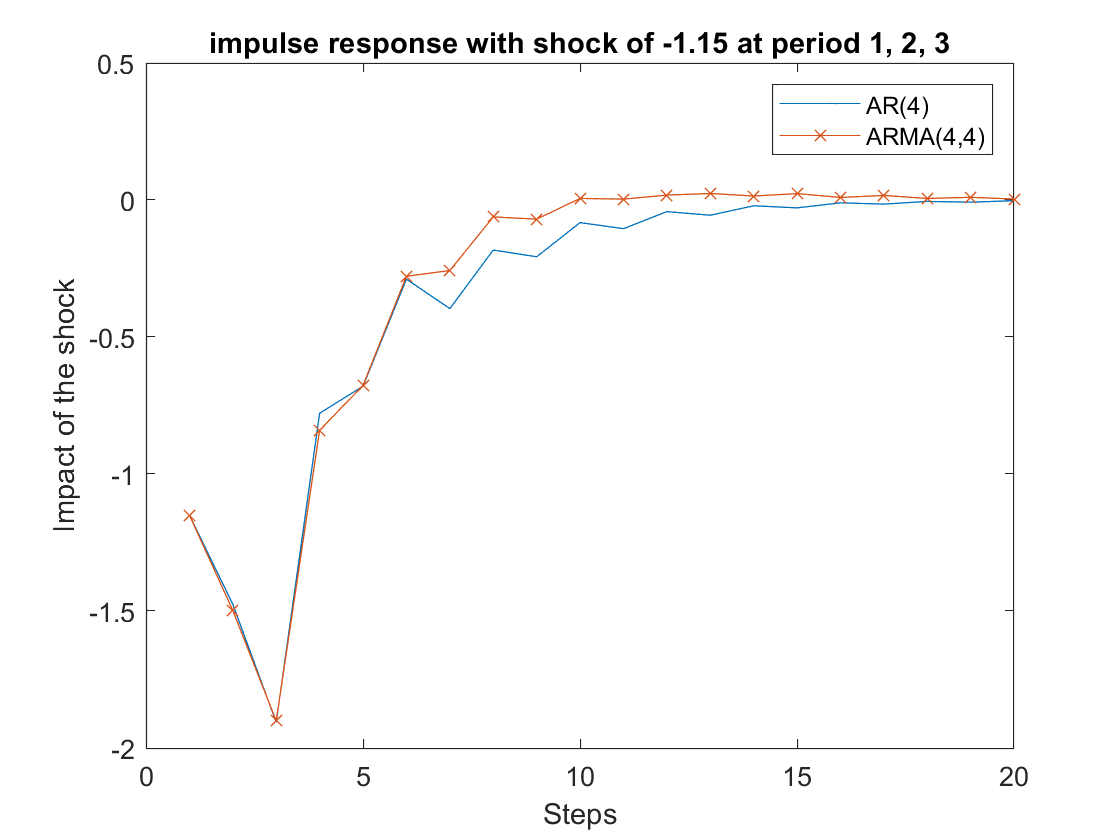

sig = -1.15;
% model 1
psi_AR4_neg = zeros(20,3);
psi_mdl1 = impulse(results(4),'numobs',20);

%first at t
psi_AR4_neg(1:20,1) = psi_mdl1(1:20)*sig;

%second shock at t+1
psi_AR4_neg(2:20,2) = psi_mdl1(1:19)*sig;

% third shock at t+2
psi_AR4_neg(3:20,3) = psi_mdl1(1:18)*sig;

%total response 
psi_AR4total_neg = sum(psi_AR4_neg,2);

% model 2 ARMA(4,4)
psi_ARMA44_neg = zeros(20,3);
psi_mdl2 = impulse(results(8),'numobs',20);

%first at t
psi_ARMA44_neg(1:20,1) = psi_mdl2(1:20)*sig;

%second shock at t+1
psi_ARMA44_neg(2:20,2) = psi_mdl2(1:19)*sig;

% third shock at t+2
psi_ARMA44_neg(3:20,3) = psi_mdl2(1:18)*sig;

%total response 
psi_ARMA44total_neg = sum(psi_ARMA44_neg,2);

%% GRAPH IMPULSE RESPONSE 
figure
plot(1:20,psi_AR4total_neg,1:20,psi_ARMA44total_neg,'-x')
legend('AR(4)','ARMA(4,4)')
xlabel('Steps')
ylabel('Impact of the shock')
title('impulse response with shock of -1.15 at period 1, 2, 3')

Interpretation:

We see that for both the AR(4) and the ARMA(4,4) models, the dynamic response starts from sigma (-1.15) corresponding to the shock at period 1, and the magnitude of the shock is increased by 2 additional shocks at period 2 and period 3, then the response converges upwards to zero quickly. 

The effect of the shock is transitory and oscillatory, for the same reasoning as in the previous question where the model was affected by a positive shock. 

**3.c) Forecasting: Split the sample into a training sample and a holdout sample. The holdout sample should consist of the last 34 observations. **

- Re-estimate the two selected models using only the training sample. 

- For each of the two models, calculate the 1-step ahead forecasts: $E_t(USDCAD_{t+1})$ for the AR(4) and ARMA(4,4). These conditional expectations are not the same!

- Plot these foecasts along with the actual (first-difference) series on the same graph for the period covered by the hold-out sample. 

- Plot the actual series (raw data in levels) against the 1-step ahead forecasts and the naive forecast:  $E_t(USDCAD_{t+1})=USDCAD_t$.  

T = length(d_sp);
training = T - 34; 

% Splitting the data into a training sample and a holdout sample:
T_sample = d_sp(1:training);                    % Training sample  
H_sample = d_sp((T-33):T);                      % Holdout sample

%re-estimating the AR(4) model:
Mdl = arima(4,0,0); % 4 lag order
[AR4_new,EstimatedCov_AR4_new,logL_AR4_new,info_AR4_new] = estimate(Mdl, T_sample);

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.010568      0.054616        -0.1935          0.84656
    AR{1}         0.30229      0.035941         8.4108       4.0711e-17
    AR{2}         0.31088       0.03215         9.6697       4.0559e-22
    AR{3}        -0.19405      0.035009         -5.543       2.9729e-08
    AR{4}         0.14477      0.037752         3.8347       0.00012574
    Variance       1.3139      0.041751          31.47      2.2253e-217





%re-estimating the ARMA(4,4) model:
Mdl = arima(4,0,4); % 2 lag orders
[ARMA44_new,EstimatedCov_ARMA44_new,logL_ARMA44_new,info_ARMA44_new] = estimate(Mdl, T_sample);

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.017668      0.057514        -0.30719          0.7587
    AR{1}         0.78059      0.083925           9.301      1.3915e-20
    AR{2}          0.1789      0.093091          1.9218        0.054634
    AR{3}         -0.7689      0.037887         -20.294      1.4406e-91
    AR{4}          0.2703      0.069743          3.8756      0.00010635
    MA{1}         -0.4854      0.088831         -5.4644      4.6455e-08
    MA{2}       -0.061512      0.092927        -0.66195         0.50801
    MA{3}         0.55796  

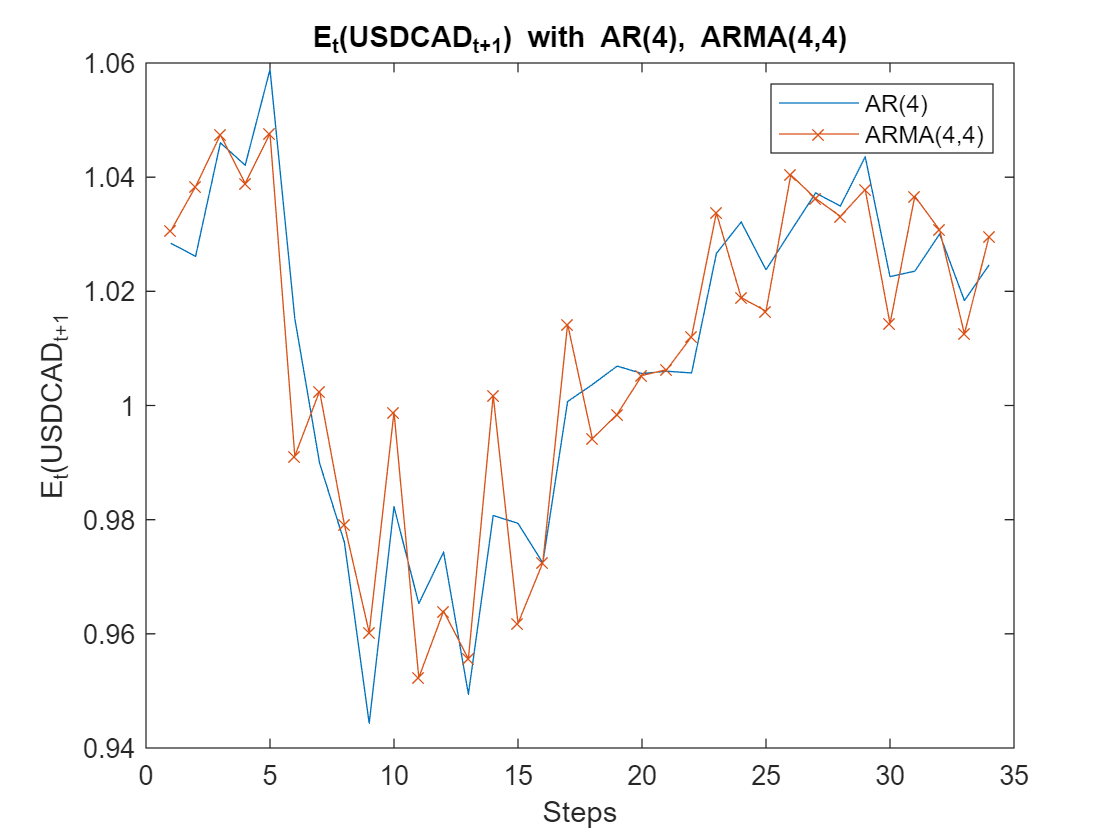


% forecasting the 1-step forecast using the forecast function from the econometrics toolbox
nstep = 34;

f_sp_AR4 = zeros(nstep,1); % Initializing the forecast vector for AR(4)
for i = 1:nstep
    [f_sp,YMSE] = forecast(AR4_new,1, 'Y0', d_sp(T-(34+4-(i-1)):T-(34-(i-1))) ); % Estimating 1 step forecast
    f_sp_AR4(i,1)= f_sp; % Saving forecast in the f_sp_AR4 vector
end

f_sp_ARMA44 = zeros(nstep,1); % Initializing the forecast vector for ARMA(4,4)
for i = 1:nstep
    [f_sp,YMSE] = forecast(ARMA44_new,1, 'Y0', d_sp(T-(34+4-(i-1)):T-(34-(i-1))) ); % Estimating 1 step forecast
    f_sp_ARMA44(i,1)= f_sp; % Saving forecast in the f_sp_ARMA44 vector
end

% Transforming AR(4) and ARMA(4,4) forecasts from percentages to values
f_USDCAD_AR4 = zeros(nstep,1);
f_USDCAD_ARMA44 = zeros(nstep,1);

for i = 1:nstep
    f_USDCAD_AR4(i) = data.shareprice(T-34+(i-1))*exp(f_sp_AR4(i)/100);
    f_USDCAD_ARMA44(i) = data.shareprice(T-34+(i-1))*exp(f_sp_ARMA44(i)/100);
    %f_USDCAD_AR4(i) = data.shareprice(T-34+(i-1))*(1+f_sp_AR4(i)/100);
    %f_USDCAD_ARMA44(i) = data.shareprice(T-34+(i-1))*(1+f_sp_ARMA44(i)/100);
end;


% Ploting both conditional expecation   
figure
steps = [1:34];
plot(steps,f_USDCAD_AR4,steps,f_USDCAD_ARMA44, '-x');
legend('AR(4)','ARMA(4,4)');
title('E_{t}(USDCAD_{t+1}) with AR(4), ARMA(4,4)')
xlabel('Steps')
ylabel('E_{t}(USDCAD_{t+1}')

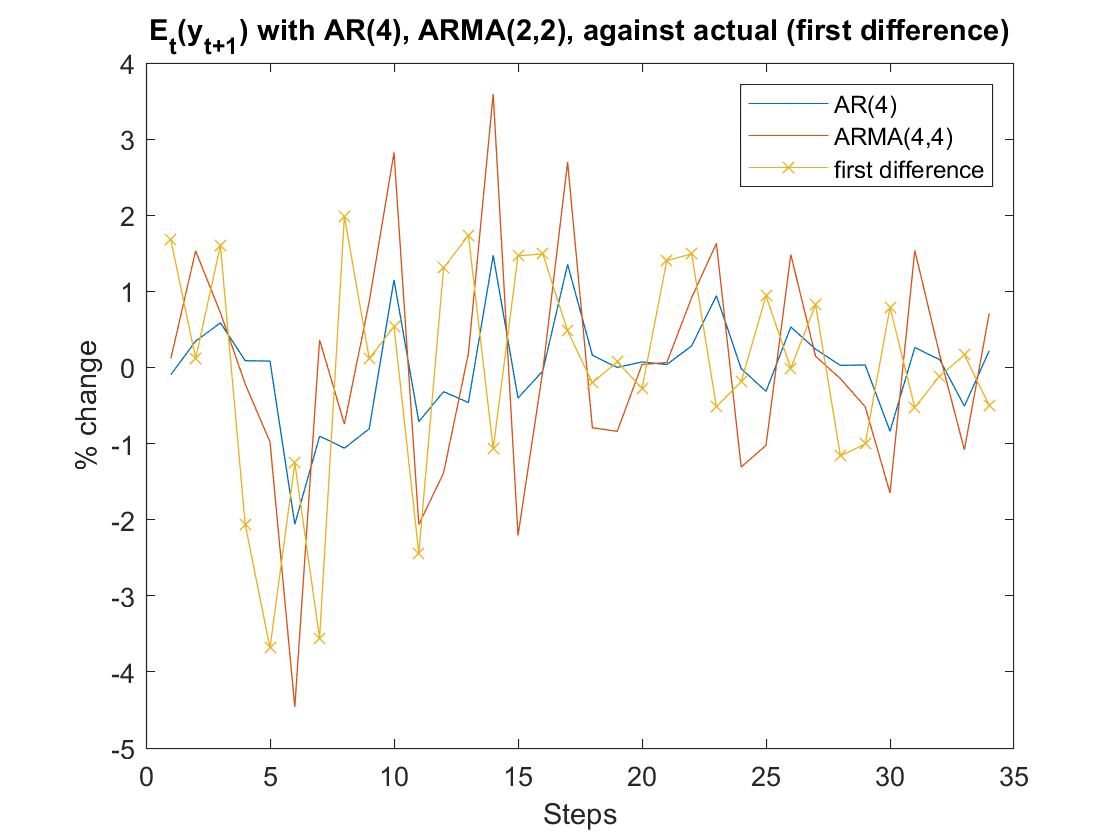


% Ploting both forecasts vs the first difference series 
figure
steps = [1:34];
plot(steps,f_sp_AR4,steps,f_sp_ARMA44,steps,H_sample, '-x');
legend('AR(4)','ARMA(4,4)','first difference');
title('E_{t}(y_{t+1}) with AR(4), ARMA(2,2), against actual (first difference)')
xlabel('Steps')
ylabel('% change')

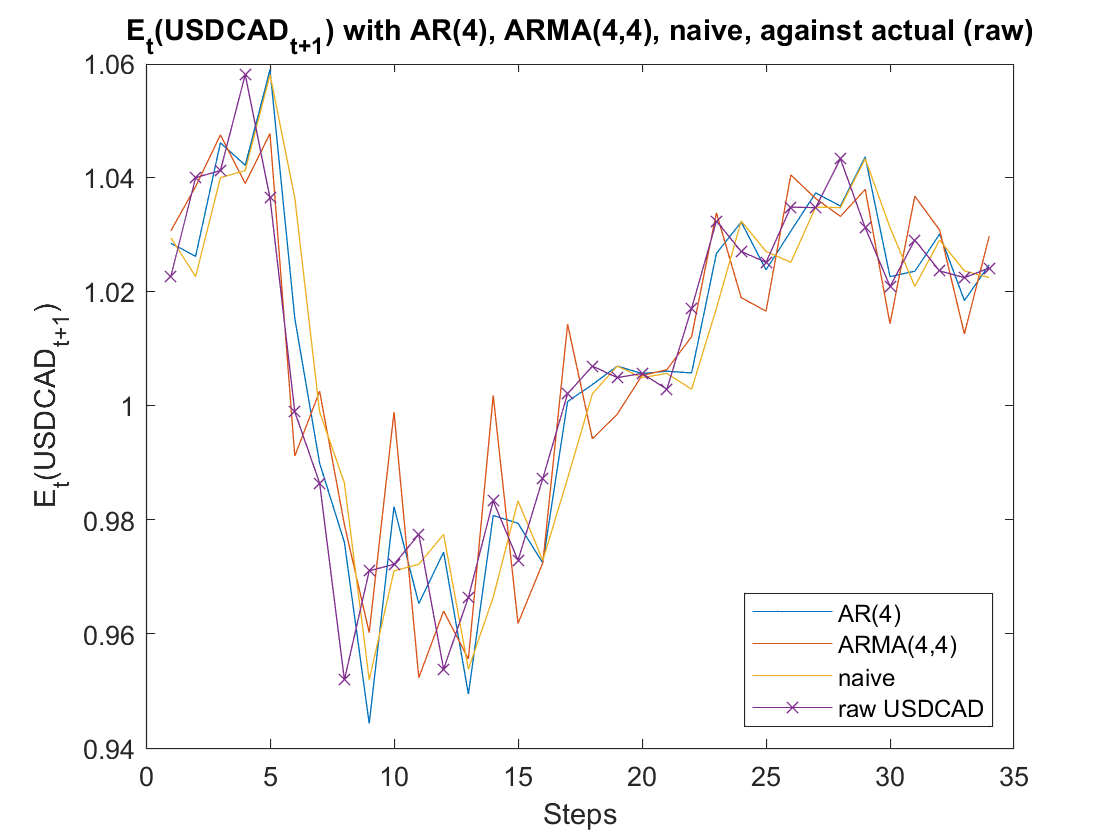

% forecast raw data

%naive forecast raw data 
raw_USDCAD = data.shareprice(T-33:T);                  % raw series

% Generating the Naive Forecast (where USDCAD(t) = USDCAD(t-1)
f_USDCAD_Naive = zeros(nstep,1);                           % initializing vector of zeros
f_USDCAD_Naive = data.shareprice(T-nstep:T-1);

% Ploting both forecasts vs Naive forecast vs the raw series 
steps = [1:34];
figure
plot(steps,f_USDCAD_AR4,steps,f_USDCAD_ARMA44, steps,f_USDCAD_Naive, steps, raw_USDCAD,'-x');
legend('AR(4)','ARMA(4,4)','naive','raw USDCAD', 'location','southeast');
xlabel('Steps')
ylabel('E_{t}(USDCAD_{t+1})')
title('E_{t}(USDCAD_{t+1}) with AR(4), ARMA(4,4), naive, against actual (raw)')

Interpretation:

The first plot shows the conditional expectation of exchange rate (E_{t}(USDCAD_{t+1})) with the ARMA(4,4) model having more extreme forecasts than the smoother AR(4) model. This could be explained by the MA(4) part of the model which has a shorter memory than the AR(4) component of both models.

The second plot shows one step ahead forecasted (yt) using AR(4), ARMA(4,4) models against the actual first difference series. The dynamic pattern are close to the actual ones, but there are divergences, with the ARMA(4,4) exhibiting larger divergences than the AR(4).  

The third plot shows one step ahead exchange rate using AR(4), ARMA(4,4) and naive model against actual price level. We note that the naive model tends to be much closer to the actual one.The ARMA(4,4) seems to have the largest divergences to the actual series out of all the models. We should analyze the mean-squared error to record a more robust observation.

**3.d) Report the Mean-Squared Error for each model using only the hold-out sample of 34 observations to evaluate the forecast performance. Compare these statistics to the following naive estimator: **$E_t(y_{t+1})=y_t$** for h=1 only. What model should we use in each case? **

% forcast first difference using naive model  
f_Naive = d_sp((T-34):T-1); % same formula as H_sample, except 1 step behind

% Extracting the residuals for the models
[u_sp_AR4,] = infer(AR4_new, H_sample); % extracting residuals for AR(4)
[u_sp_ARMA44,] = infer(ARMA44_new, H_sample); % extracting residuals for ARMA(4,4)
u_sp_Naive = H_sample - f_Naive; % extracting residuals for Naive model

% MEAN SQUARE ERROR - AR(4)
mean_sqerr_AR4 = sum(u_sp_AR4.^2)/length(u_sp_AR4)

mean_sqerr_AR4 = 2.3103


% MEAN SQUARE ERROR - ARMA(4,4)
mean_sqerr_ARMA44 = sum(u_sp_ARMA44.^2)/length(u_sp_ARMA44)

mean_sqerr_ARMA44 = 2.3577


% MEAN SQUARE ERROR (Horizon: 1) - Naive Model
mean_sqerr_Naive = sum(u_sp_Naive.^2)/length(u_sp_Naive)

mean_sqerr_Naive = 3.8321

Interpretation:

The mean square error for the AR(4) (MSE: 2.3103) and the ARMA(4,4) (MSE: 2.3577) is notably lower than the naive model (MSE: 3.8321). This suggests that the naive model is less accurate than the AR(4) and ARMA(4,4) models when forecasting the 1-step forecast, in contrast to our observation in the previous number. As such, we should consider the AR(4) and the ARMA(4,4) models over the naive model. To this point, the AR(4) has a slightly better mean square error than the ARMA(4,4) model. As such, we should use the AR(4) model.

### Part 4. Further improvements by modelling the conditional variance (30 points)

**4.a) Plot the autocorrelation and partial autocorrelation functions of **$y_t^2$**. What can you conclude?**

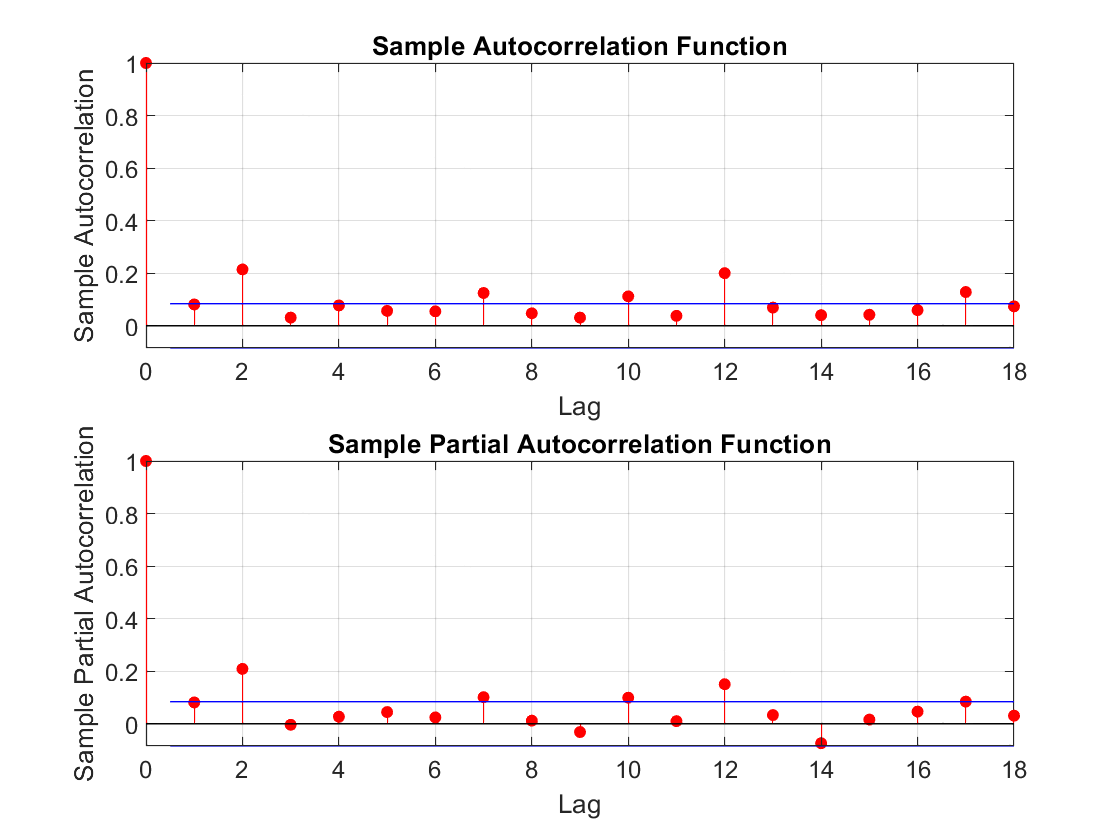

subplot(2,1,1);
autocorr(d_sp.^2,18);
%title('autocorrelations: c_sp');
%set(gca,'FontSize',8);

subplot(2,1,2);
parcorr(d_sp.^2,18);  

Interpretation:

The autocorrelation and partial autocorrelation functions of the squared series ($y_t^2$) tends to zero when i is large: the series is therefore stationary.

The partical autocorrelation of $y_t^2$ is small when i > 4, suggesting a lag structure with 4 to catch the conditional variance. 

**4.b) Estimate the ARCH(1) and GARCH(1,1) versions of the two selected models by maximum likelihood using only the training sample, and report the estimates.**

% AR(4) and ARCH(1)
Mdl = arima('ARLags',[1 2 3 4],'Variance',garch(0,1));
[AR_ARCH,EstParamCov_AR_ARCH,logL_AR_ARCH,info_AR_ARCH] = estimate(Mdl, d_sp(1:training));

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant     0.043737      0.030652         1.4269         0.15361
    AR{1}         0.42749      0.020464          20.89      6.6284e-97
    AR{2}         0.31636      0.018852         16.781      3.3376e-63
    AR{3}       -0.084374      0.025676        -3.2861       0.0010158
    AR{4}        0.020761      0.025874        0.80239         0.42233

 
 
    GARCH(0,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                <s

% AR(4) and GARCH(1,1)
Mdl = arima('ARLags',[1 2 3 4],'Variance',garch(1,1));
[AR_GARCH,EstParamCov_AR_GARCH,logL_AR_GARCH,info_AR_GARCH] = estimate(Mdl, d_sp(1:training));

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant     0.014611      0.031397        0.46536         0.64167
    AR{1}         0.26294      0.046387         5.6683      1.4423e-08
    AR{2}         0.30176      0.037348         8.0795       6.504e-16
    AR{3}       -0.051339      0.047064        -1.0908         0.27535
    AR{4}        0.087278      0.044094         1.9794        0.047774

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                <

% ARMA(4,4) and ARCH(1)
Mdl = arima('ARLags',[1 2 3 4], 'MALags',[1 2 3 4], 'Variance',garch(0,1));
[ARMA_ARCH,EstParamCov_ARMA_ARCH,logL_ARMA_ARCH,info] = estimate(Mdl, d_sp(1:training));

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.013487      0.062289        -0.21653        0.82858
    AR{1}         0.77629      0.097915          7.9282     2.2232e-15
    AR{2}        -0.75864      0.076391         -9.9311     3.0486e-23
    AR{3}         0.17225       0.09553          1.8031       0.071372
    AR{4}       -0.042725      0.044099        -0.96886        0.33262
    MA{1}        -0.23371       0.10572         -2.2107       0.027057
    MA{2}         0.61415      0.079807          7.6955     1.4097e-14
    MA{3}         0.10347      0.081

% ARMA(4,4) and GARCH(1,1)
Mdl = arima('ARLags',[1 2 3 4], 'MALags',[1 2 3 4], 'Variance',garch(1,1));
[ARMA_GARCH,EstParamCov_ARMA_GARCH,logL_ARMA_GARCH,info_ARMA_GARCH] = estimate(Mdl, d_sp(1:training));

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.012082      0.044881        -0.26921        0.78777
    AR{1}         0.85397       0.12933           6.603     4.0294e-11
    AR{2}        -0.82113      0.073874         -11.115     1.0581e-28
    AR{3}         0.25459       0.11369          2.2394       0.025132
    AR{4}       -0.064473      0.077118        -0.83603        0.40314
    MA{1}        -0.59098       0.13604          -4.344     1.3989e-05
    MA{2}         0.85427      0.094526          9.0374      1.605e-19
    MA{3}        -0.17578       0.10

Note: the estimator for AR(4)GARCH(4,4) gives us a1 + b1 = 1, which does not meet the stationary condition of a1 + b1 <1. 

**4.c) Perform likelihood ratio tests to select one model between AR(4), AR(4) ARCH(1), and AR(4) GARCH(1,1). Repeat this procedure to select one model between ARMA(4,4), ARMA(4,4) ARCH(1), and ARMA(4,4) GARCH(1,1). **

% H0: AR(4), Ha: AR4+ARCH1
LR = 2*(logL_AR_ARCH-m_ll(4,3));
pvalue = 1-chi2cdf(LR,1);
pvalue    

pvalue = 0

% pvalue is less than 5% suggesting we reject H0: AR(4) and accept H1: AR(4) ARCH(1) at 5% level 
% H0: AR(4)+ARCH1, 
% Ha: AR4+GARCH(1,1)

LR = 2*(logL_AR_GARCH-logL_AR_ARCH);
pvalue = 1-chi2cdf(LR,1);
pvalue    

pvalue = 0

% pvalue is less than 5% suggesting we reject H0: AR(4)ARMA(4,4) and accept H1: AR(4) GARCH(1,1) at 5% level 

% H0: ARMA(4,4)
% Ha: ARMA(4,4)+ARCH(1)
LR = 2*(logL_ARMA_ARCH-m_ll(8,3));
pvalue = 1-chi2cdf(LR,1);
pvalue    %reject ARMA(4)

pvalue = 0

% pvalue is less than 5% suggesting we reject H0: ARMA(4,4) and accept H1: ARMA(4,4) ARCH(1) at 5% level 
% H0: ARMA(4,4)+ARCH(1), 
% Ha: ARMA(4,4)+GARCH(1,1)

LR = 2*(logL_ARMA_GARCH-logL_ARMA_ARCH);
pvalue = 1-chi2cdf(LR,1);
pvalue

pvalue = 0

% pvalue is less than 5% suggesting we have significant evidence to reject H0: ARMA(4,4) ARCH(1) 
% and accept H1: ARMA(4,4) GARCH(1,1) at 5% significant level 

Interpretation: 

The likelihood ratio tests suggest we choose AR(4)GARCH(1,1) and ARMA(4)GARCH(1,1). 

**4.d) Perform a specification test on the residuals for AR(4) ARCH(1) and AR(4) GARCH(1,1). What is the best model for the conditional variance?**

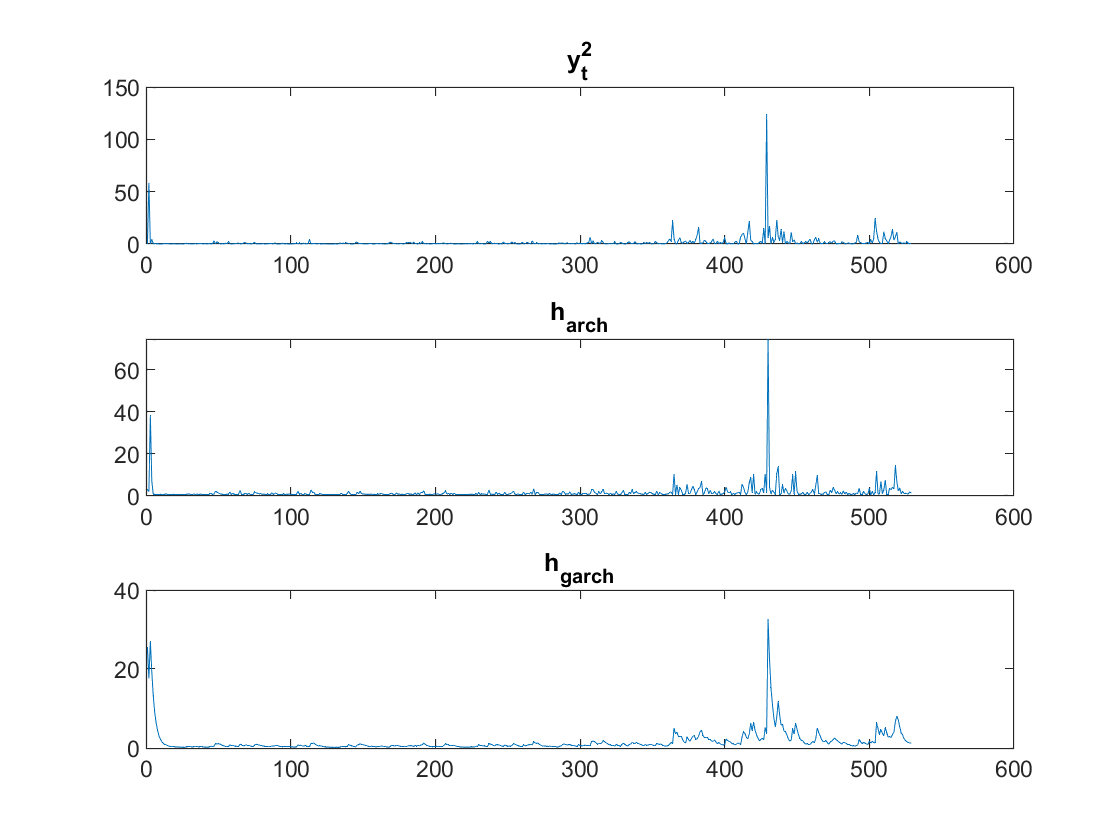

%% Specification Test
u_sp_arch = infer(AR_ARCH,d_sp(1:training));
u_sp_garch = infer(AR_GARCH,d_sp(1:training));

u_sp2_arch = u_sp_arch.^2;
u_sp2_garch = u_sp_garch.^2;

% AR(4) and ARCH(1)
alpha_1_arch = AR_ARCH.Variance.ARCH{1};
alpha_0_arch = AR_ARCH.Variance.Constant;

h_arch = nan*u_sp_arch;
h_arch(1) = alpha_0_arch + alpha_1_arch*alpha_0_arch/(1-alpha_1_arch);

for t = 2:training
    h_arch(t)     = alpha_0_arch+alpha_1_arch*u_sp2_arch(t-1);
end

%AR(4) and GARCH(1,1)
beta_garch = ARMA_GARCH.Variance.GARCH{1};
alpha_1_garch = ARMA_GARCH.Variance.ARCH{1};
alpha_0_garch = ARMA_GARCH.Variance.Constant;
h_garch = nan*u_sp_garch;
h_garch(1) = alpha_0_garch + alpha_1_garch*alpha_0_garch/(1-alpha_1_garch-beta_garch);

for t = 2:training
    h_garch(t)     = alpha_0_garch+alpha_1_garch*u_sp2_garch(t-1)+beta_garch*h_garch(t-1);
end



%% Plot conditional variance

figure

subplot(3,1,1) 
plot(d_sp(1:training).^2)
title('y_{t}^2')

subplot(3,1,2)
plot(h_arch)
title('h_{arch}') 

subplot(3,1,3)
plot(h_garch)
title('h_{garch}')

The ARCH(1) and GARCH(1,1) capture the notion of alternating episodes of high volatility and low volatility. The conditional variance associated with the GARCH(1,1) seems more persistant than that obtained from the ARCH(1). This is explained by the fact that the temporal dependence parameters of the GARCH(1,1), where (alpha1+beta1) = 0.7 + 0.29 = 0.99, is larger than the temporal dependence parameter for the ARCH(1), where alpha1 = 0.78.

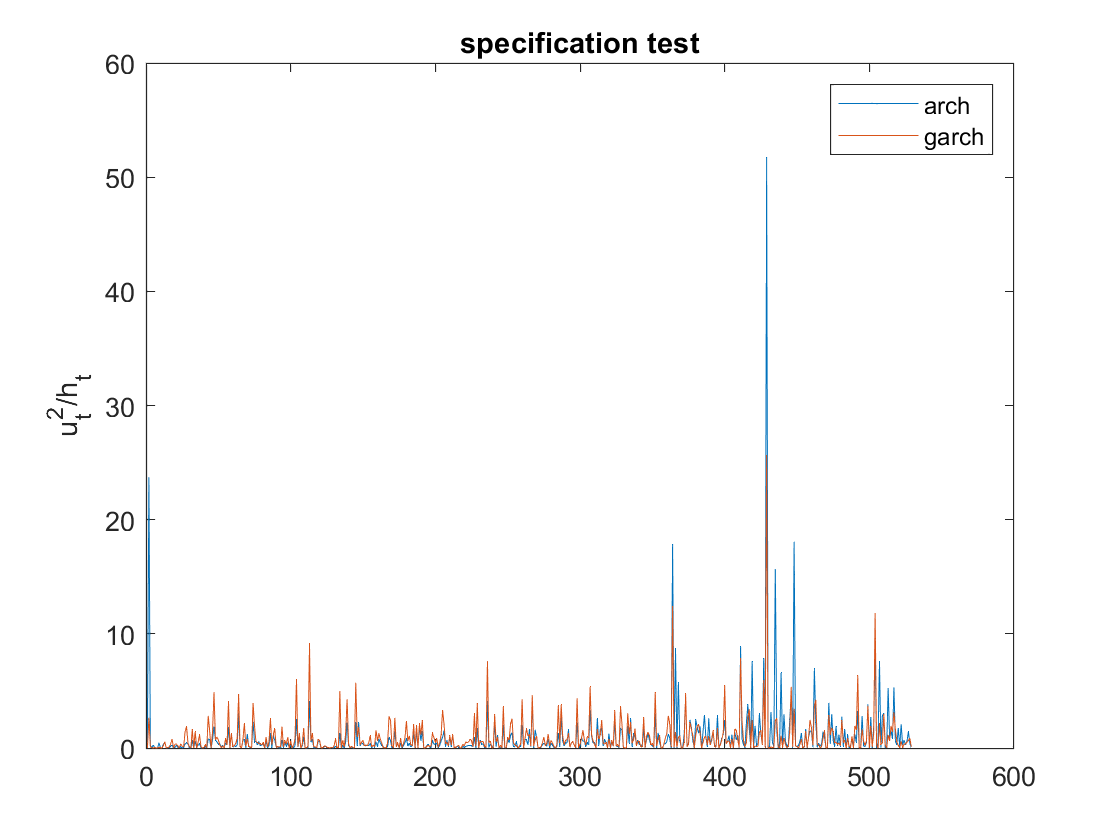

% specification test 
test_arch = u_sp2_arch./h_arch;
test_garch= u_sp2_garch./h_garch;

figure 
plot((test_arch))
hold on
plot((test_garch))
title('specification test')
ylabel('u_{t}^2/h_{t}')
legend('arch','garch')
hold off


[acf_arch]  = autocorr(test_arch(4+1:training),18);
[acf_garch] = autocorr(test_garch(4+1:training),18);

[h1_arch,pValue_arch,stat_arch] = lbqtest(test_arch(4+1:training),'lags',1:18)

h1_arch = 1×18 logical array
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


pValue_arch =     0.2823    0.0037    0.0044    0.0064    0.0104    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


stat_arch =     1.1561   11.2045   13.0949   14.3142   14.9952   34.9033   35.0887   36.4455   37.2161   53.0280   53.0560   56.0459   61.4608   62.9541   63.1721   66.3852   67.9399   73.0992



[h1_garch,pValue_garch,stat_garch] = lbqtest(test_garch(4+1:training),'lags',1:18)

h1_garch = 1×18 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


pValue_garch =     0.1806    0.2101    0.2491    0.3378    0.4744    0.5910    0.7011    0.5521    0.5646    0.6556    0.7267    0.5455    0.6253    0.6604    0.5933    0.6611    0.3440    0.1742


stat_garch =     1.7930    3.1207    4.1168    4.5400    4.5413    4.6383    4.6619    6.8570    7.7004    7.7262    7.8503   10.8076   10.8268   11.3236   13.1170   13.1594   18.7340   23.4416


Interpretation:

H0: ut^2/ht has no autocorrelation for all the lags, while H1: ut^2/ht has autocorrelation at least one lag. 

The Ljung-Box test rejects the null hypothesis for the AR(4) ARCH(1) model. With a significance level of alpha = 0.05, we can infer that the model is not an adequate speicfication of the conditional variance.

However, the Ljung-Box test for the AR(4) GARCH(1,1) model does not reject the null hypothesis, suggesting that the residual from the specification of the conditional variance is white noise and that the model is an adequate speicfication of the conditional variance.

**4.e) For these two new models and the two models studied in Part 3, plot the impulse response functions of the second case described in Part 3. How different are they?**

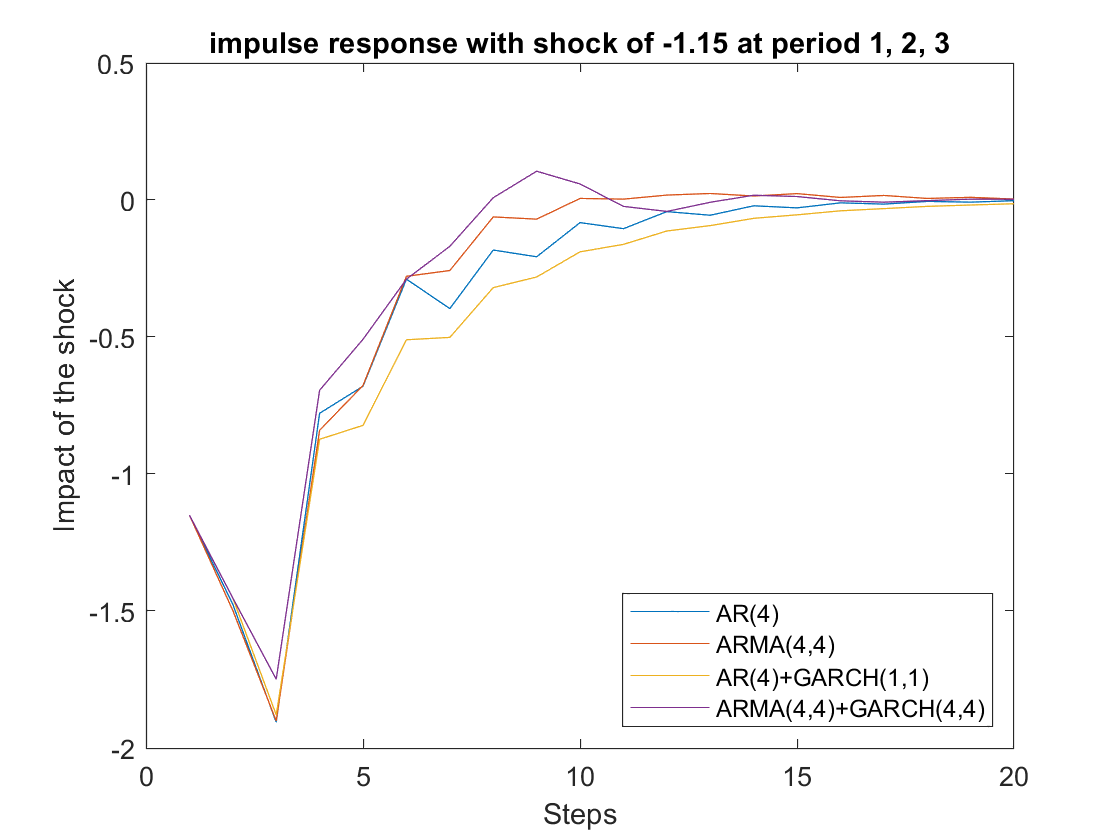

% model1 AR(4) and GARCH(1,1)
% model2 ARMA(4,4) and GARCH(1,1) 
% model3 AR(4) 
% model4 ARMA(4,4)

sig = -1.15;
% model 1
psi_argarch = zeros(20,3);
psi_mdl3 = impulse(AR_GARCH,'numobs',20);

%first at t
psi_argarch(1:20,1) = psi_mdl3(1:20)*sig;   % shift the shock one period 

%second shock at t+1
psi_argarch(2:20,2) = psi_mdl3(1:19)*sig;   % shift the shock two periods

% third shock at t+2
psi_argarch(3:20,3) = psi_mdl3(1:18)*sig;   % shift the shock three periods

%total response 
psi_argarch_total = sum(psi_argarch,2);     % sum the three shocks 


% model 2
psi_armagarch = zeros(20,3);
psi_mdl4 = impulse(ARMA_GARCH,'numobs',20);

%first shock at t
psi_armagarch(1:20,1) = psi_mdl4(1:20)*sig;  % shift the shock one period 

%second shock at t+1
psi_armagarch(2:20,2) = psi_mdl4(1:19)*sig;  % shift the shock two periods

% third shock at t+2
psi_armagarch(3:20,3) = psi_mdl4(1:18)*sig;  % shift the shock three periods

%total response 
psi_armagarch_total = sum(psi_armagarch,2);  % sum the three shocks 

%% GRAPH IMPULSE RESPONSE 
figure(5)
plot(1:20,psi_AR4total_neg,1:20,psi_ARMA44total_neg,1:20, psi_argarch_total, 1:20, psi_armagarch_total);
legend('AR(4)','ARMA(4,4)', 'AR(4)+GARCH(1,1)','ARMA(4,4)+GARCH(4,4)', 'location','southeast');
xlabel('Steps');
ylabel('Impact of the shock');
title('impulse response with shock of -1.15 at period 1, 2, 3');

AR_GARCH.AR   %(AR4GARCH44)

ans = 1×4 cell array
    {[0.2629]}    {[0.3018]}    {[-0.0513]}    {[0.0873]}


results(4).AR     %AR4

ans = 1×4 cell array
    {[0.2830]}    {[0.2942]}    {[-0.1697]}    {[0.1295]}


ARMA_GARCH.AR       %ARMA44GARCH11

ans = 1×4 cell array
    {[0.8540]}    {[-0.8211]}    {[0.2546]}    {[-0.0645]}


results(8).AR       %ARMA44

ans = 1×4 cell array
    {[-0.0830]}    {[1.0015]}    {[0.0941]}    {[-0.3087]}


Interpretation:

The dynamic response = phi^i, is determined from the level equation, AR(4) or ARMA(4,4), therefore, the dynamic response should be the same whether or not there is conditional heteroscedasticity. 

However, the conditional variance in the garch model varies while the variance in the AR model is constant, resulting in the MLE of phi being different in the level equation, leading to the difference in the dynamic response. 

**4.f) Like in Part 3, plot the 1-step ahead forecasts for **$y_t$** for the period covered by the holdout sample. Compare them with those obtained in Part 3. **

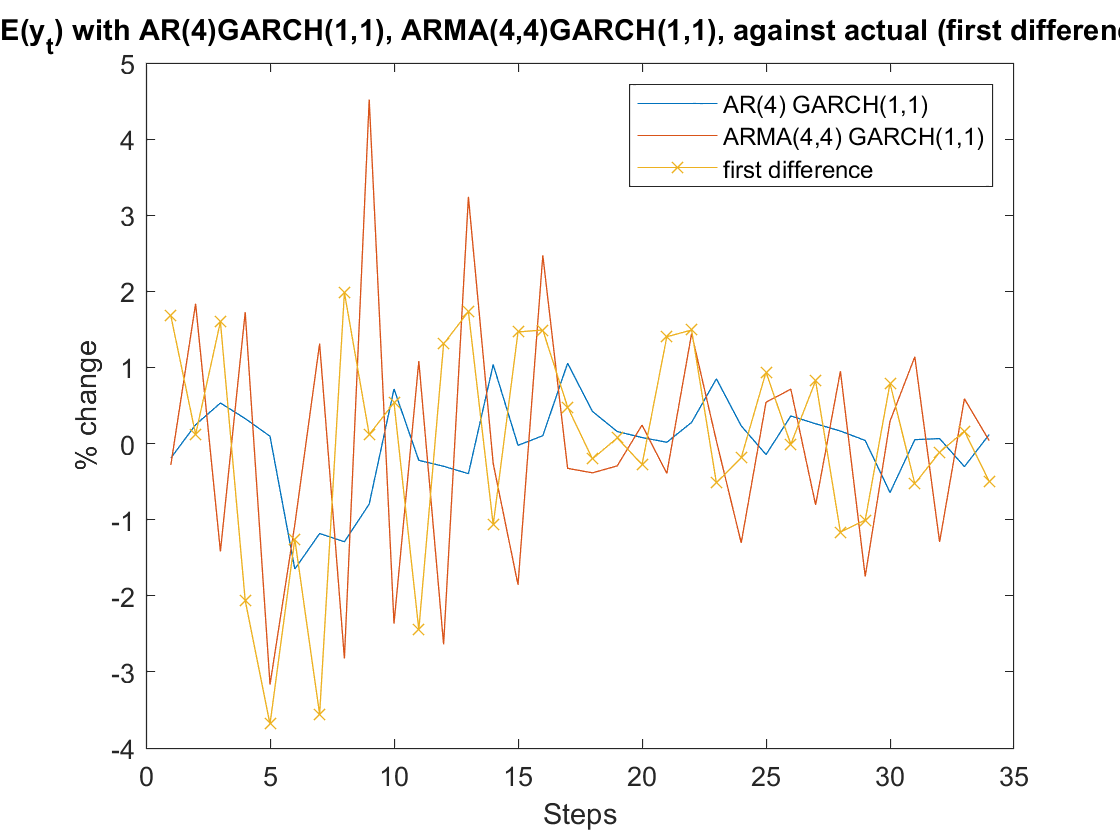

% forecasting the 1-step forecast using the forecast function from the econometrics toolbox
nstep = 34;

f_sp_ARGARCH = zeros(nstep,1); % Initializing the forecast vector for AR(4)
for i = 1:nstep
    [f_sp,YMSE] = forecast(AR_GARCH,1, 'Y0', d_sp(T-(34+4-(i-1)):T-(34-(i-1))) ); % Estimating 1 step forecast
    f_sp_ARGARCH(i,1)= f_sp; % Saving forecast in the f_sp_ARGARCH vector
end

f_sp_ARMAGARCH = zeros(nstep,1); % Initializing the forecast vector for ARMA(4,4)
for i = 1:nstep
    [f_sp,YMSE] = forecast(ARMA_GARCH,1, 'Y0', d_sp(T-(34+4-(i-1)):T-(34-(i-1))) ); % Estimating 1 step forecast
    f_sp_ARMAGARCH(i,1)= f_sp; % Saving forecast in the f_sp_ARMAGRARCH vector
end

% Ploting both forecasts vs the first difference series 
figure
steps = [1:34];
plot(steps,f_sp_ARGARCH,steps,f_sp_ARMAGARCH,steps,H_sample, '-x');
legend('AR(4) GARCH(1,1)','ARMA(4,4) GARCH(1,1)','first difference');
title('E(y_{t}) with AR(4)GARCH(1,1), ARMA(4,4)GARCH(1,1), against actual (first difference)')
xlabel('Steps')
ylabel('% change')

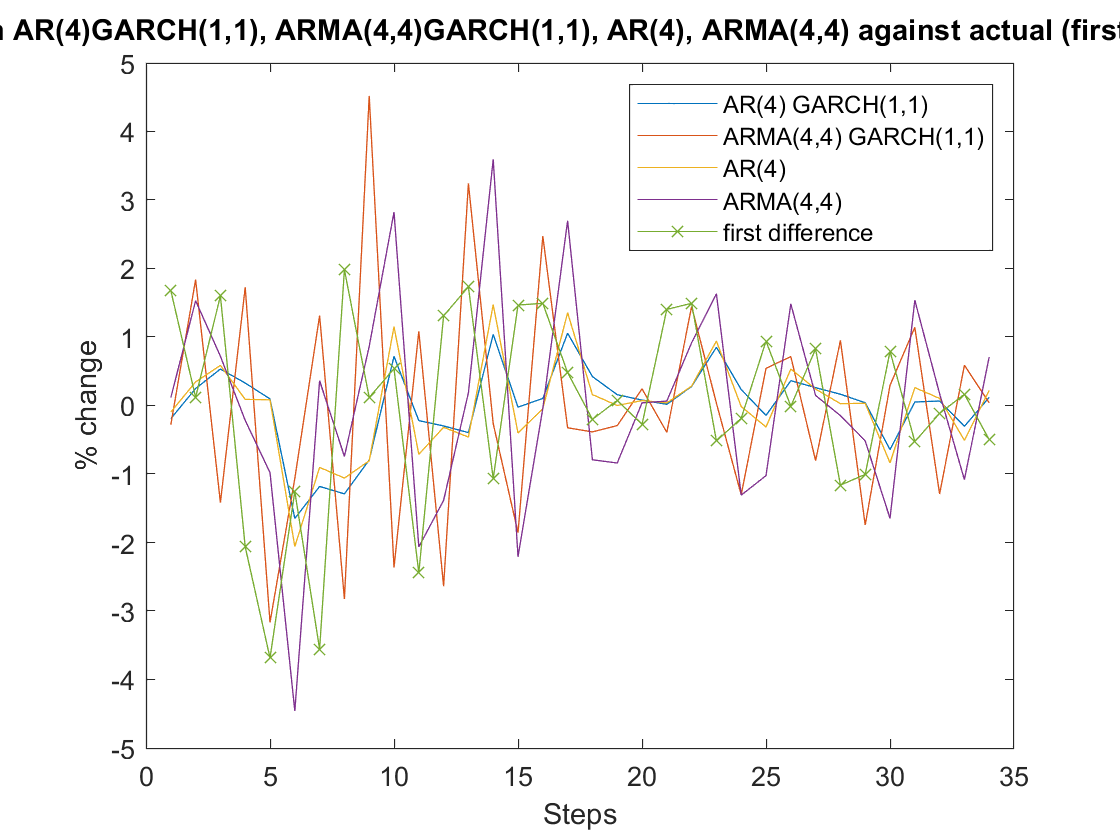

% Ploting both forecasts vs AR(4) and ARMA(4,4) vs the first difference series 
figure
steps = [1:34];
plot(steps,f_sp_ARGARCH,steps,f_sp_ARMAGARCH,steps,f_sp_AR4,steps,f_sp_ARMA44, steps,H_sample, '-x');
legend('AR(4) GARCH(1,1)','ARMA(4,4) GARCH(1,1)','AR(4)','ARMA(4,4)','first difference');
title('E(y_{t}) with AR(4)GARCH(1,1), ARMA(4,4)GARCH(1,1), AR(4), ARMA(4,4) against actual (first difference)')
xlabel('Steps')
ylabel('% change')

Interpretation:

The first plot shows one step ahead forecast (yt) using AR(4)GARCH(4,4), ARMA(4,4) GARCH(4,4) against the actual first difference series. The forecast error for the ARMA(4,4) GARCH(4,4) appears to be larger than its peer.  

The second plot shows one step ahead forecast using AR(4)GARCH(4,4), ARMA(4,4)GARCH(4,4), and AR(4), ARMA(4,4) against the actual series. The forecasts are determined from the level equation, regardless of the presence of conditional heteroscedasticity, however, as explained above for the dynamic response, the MLE is different with the presence of varying conditional variance, which leads to the different phi, such that the forecast is different between the peers with the same level equation. 

**4.g) Compare the Mean-Squared Errors of the 1-step ahead forecast (for the transformed series!) for the two models selected in Part 3, the two new models, the naive forecast **$E_t(y_{t+1})=y_t$**, and the *****lazy***** forecast **$E_t(y_{t+1})=0$** for all t. The latter assumes that the series in levels will not change. What can you conclude? Was modelling the conditional covariance useful?**

% lasy forecast
f_lasy = zeros(34,1);

% Extracting the residuals for the models
[u_sp_ARGARCH,] = infer(AR_GARCH, H_sample); % extracting residuals for AR(4)
[u_sp_ARMAGARCH,] = infer(ARMA_GARCH, H_sample); % extracting residuals for ARMA(4,4)
u_sp_Naive = H_sample - f_Naive; % extracting residuals for Naive model
u_sp_lasy = H_sample - f_lasy; % extracting residuals for Naive model


% MEAN SQUARE ERROR - AR(4)
mean_sqerr_AR4;

% MEAN SQUARE ERROR - ARMA(4)
mean_sqerr_ARMA44;

% MEAN SQUARE ERROR - AR(4) GARCH(1,1)
mean_sqerr_AR4_GARCH11 = sum(u_sp_ARGARCH.^2)/length(u_sp_ARGARCH);

% MEAN SQUARE ERROR - ARMA(4) GARCH(1,1)
mean_sqerr_ARMA4_GARCH11 = sum(u_sp_ARMAGARCH.^2)/length(u_sp_ARMAGARCH);

% MEAN SQUARE ERROR (Horizon: 1) - Naive Model
mean_sqerr_Naive = sum(u_sp_Naive.^2)/length(u_sp_Naive);

% MEAN SQUARE ERROR (Horizon: 1) - Lazy Forecast
mean_sqerr_lasy = sum(u_sp_lasy.^2)/length(u_sp_lasy);
mean_sqerr = [mean_sqerr_AR4,mean_sqerr_ARMA44,mean_sqerr_AR4_GARCH11,mean_sqerr_ARMA4_GARCH11,mean_sqerr_Naive,mean_sqerr_lasy];
colNames = {'AR(4)','ARMA(4,4)','AR(4)GARCH(1,1)','ARMA(4,4)GARCH(1,1)','Naive','Lazy'};
sTable = array2table(mean_sqerr,'VariableNames',colNames);
sTable

sTable = 1×6 table
    AR(4)     ARMA(4,4)    AR(4)GARCH(1,1)    ARMA(4,4)GARCH(1,1)    Naive      Lazy 
    ______    _________    _______________    ___________________    ______    ______

    2.3103     2.3577          2.2121               2.3373           3.8321    1.9961


Interpretation:

Amongst all models, the lazy model forecast has the lowest mean square error.  

AR(4)GARCH(1,1) has the best performance amongst the models we derived (excluding the lazy and naive models).